# Metodo de Biseccion

clear;
clc;
syms x;
f = (x^3)-((x^2)/2)-3*x+2

$$f = x^{3}-\frac{x^{2}}{2}-3\,x+2$$

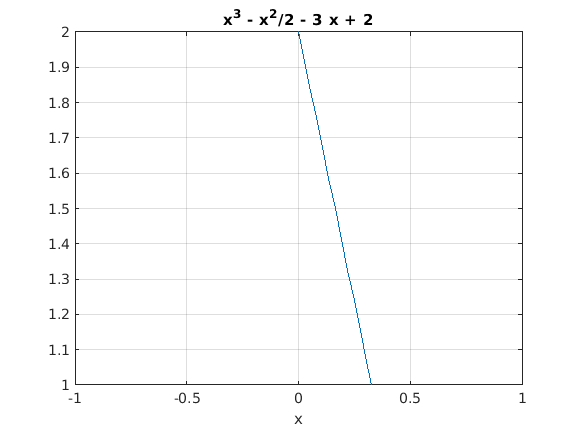

Antes del ciclo: 


EA = 2

ER = Inf

Iteración: 1


La raíz en la iteración es:  0.5


El error absoluto en la iteración es: 0.5


El error relativo en la iteracion es:1


*


Iteración: 2


La raíz en la iteración es:  0.75


El error absoluto en la iteración es: 0.10938


El error relativo en la iteracion es:0.14583


*


Iteración: 3


La raíz en la iteración es:  0.625


El error absoluto en la iteración es: 0.17383


El error relativo en la iteracion es:0.27813


*


Iteración: 4


La raíz en la iteración es:  0.6875


El error absoluto en la iteración es: 0.026123


El error relativo en la iteracion es:0.037997


*


Iteración: 5


La raíz en la iteración es:  0.71875


El error absoluto en la iteración es: 0.043243


El error relativo en la iteracion es:0.060165


*


Iteración: 6


La raíz en la iteración es:  0.70312


El error absoluto en la iteración es: 0.0089531


El error relativo en la iteracion es:0.012733


*


Iteración: 7


La raíz en la iteración es:  0.69531


El error absoluto en la iteración es: 0.0084882


El error relativo en la iteracion es:0.012208


*


Iteración: 8


La raíz en la iteración es:  0.69922


El error absoluto en la iteración es: 0.00025684


El error relativo en la iteracion es:0.00036732


*


Iteración: 9


La raíz en la iteración es:  0.69727


El error absoluto en la iteración es: 0.0041096


El error relativo en la iteracion es:0.0058939


*


Iteración: 10


La raíz en la iteración es:  0.69824


El error absoluto en la iteración es: 0.0019249


El error relativo en la iteracion es:0.0027567


*


Iteración: 11


La raíz en la iteración es:  0.69873


El error absoluto en la iteración es: 0.00083363


El error relativo en la iteracion es:0.0011931


*


Iteración: 12


La raíz en la iteración es:  0.69897


El error absoluto en la iteración es: 0.0002883


El error relativo en la iteracion es:0.00041246


*


Iteración: 13


La raíz en la iteración es:  0.6991


El error absoluto en la iteración es: 1.5709e-05


El error relativo en la iteracion es:2.2471e-05


*


La raíz es: 


    0.6991



a = -1;
b = 1;
tol = 10^-4;
ezplot(f)
axis([a b 1 2]);
grid on;
fa = double(subs(f,a));
fb = double(subs(f,b));
if(fa * fb < 0)
    disp('Antes del ciclo: ')
    xr = double((a+b)/2);
    fxr = double(subs(f, xr)); 
    EA = abs(fxr) %Error absoluto
    ER = abs(fxr/xr) %Error relativo 
    i = 0;
    while (ER > tol) % 
        if(fa * fxr < 0)
            b = xr;
            fb = double(subs(f, b));
        else
            a = xr;
            fa = double(subs(f,a));
        end
        xr = double((a+b)/2);
        fxr = double(subs(f,xr));
        EA = abs(fxr);
        ER = double(abs(fxr/xr));
        disp(['Iteración: ', num2str(i+1)]);
        disp(['La raíz en la iteración es:  ', num2str(xr)]);
        disp(['El error absoluto en la iteración es: ', num2str(EA)]);
        disp(['El error relativo en la iteracion es:',num2str(ER)]);
        disp('*')
        i = i+1;
    end
    disp('La raíz es: ');
    disp(xr);
    hold on;
    plot(xr, 0, 'r*');
end